# Week 9 Lecture 3: Boundary Value Problems

## Rahman notes:

### Shooting Method

First let's use the "shooting method".  With this method we solve the problem as an initial value problem, and use root finding to match the value on the other side.  For example, with

$\ddot{x} = 0$, with $x(0) = x_0$ and $x(T) = x_T$.  

we start by solving $\ddot{x} = 0$, with $x(0) = x_0$, $x'(0) = v_1$ and $\ddot{x} = 0$, with $x(0) = x_0$, $x'(0) = v_2$ such that the first IVP produces $x(T) = x_a > x_T$ and the second IVP produces $x(T) = x_b < x_T$.  Now, using bisection we can adjust until we match $x(T) \approx x_T$.

Let's try it with

$\ddot{x} = 0$ with $x(0) = 1$ and $x(3) = 5$.  

x0 = 1;
v1 = 0;
v2 = 1;

%%% Test v1 and v2
[T, Y] = ode45(@(t, x) myODE(t,x), [0 3], [x0 v1]);
Y(end, 1)

ans = 1


[T, Y] = ode45(@(t, x) myODE(t,x), [0 3], [x0, v2]);
Y(end,1)

ans = 4.0000

That's no good because they are both less than 5.  Lets not change v2, but lets try to find v1 that will give us a value greater than 5.

x0 = 1;
v1 = 2;
v2 = 1;
xT = 5;

%%% Test v1 and v2
[T, Y] = ode45(@(t, x) myODE(t,x), [0 3], [x0 v1]);
Y(end, 1)

ans = 7.0000


[T, Y] = ode45(@(t, x) myODE(t,x), [0 3], [x0, v2]);
Y(end,1)

ans = 4.0000

This works because one is bigger than 5 and the other is less than 5.  Now let's write our bisection scheme.

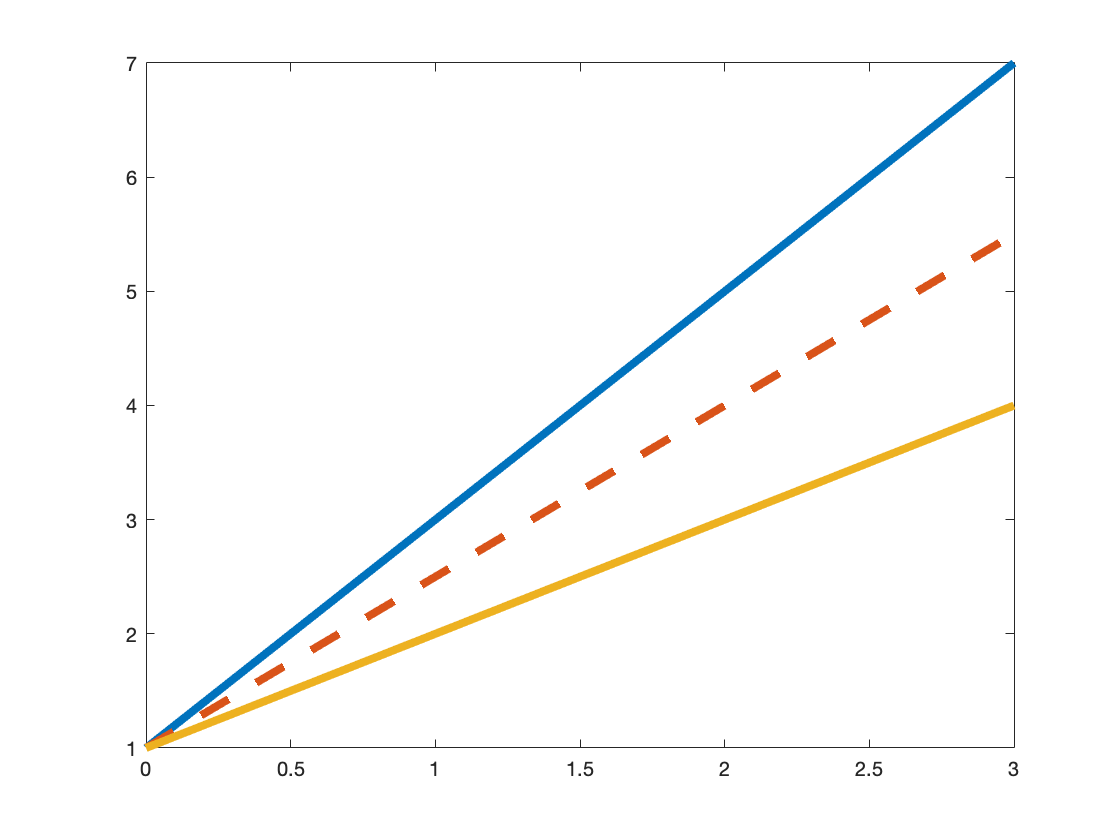

x0 = 1;
v1 = 2;
v2 = 1;
xT=5;

v_mid = (v1 + v2)/2;

[T, Y] = ode45(@(t, x) myODE(t,x), [0 3], [x0 v1]);
t_a = T; % for plotting
x_a = Y(:, 1);
[T, Y] = ode45(@(t, x) myODE(t,x), [0 3], [x0 v2]);
t_b = T; % for plotting
x_b = Y(:, 1);
[T, Y] = ode45(@(t, x) myODE(t,x), [0 3], [x0 v_mid]);
t_mid = T; % for plotting
x_mid = Y(:, 1);

plot(t_a, x_a, t_mid, x_mid, '--', t_b, x_b, 'linewidth', 4)

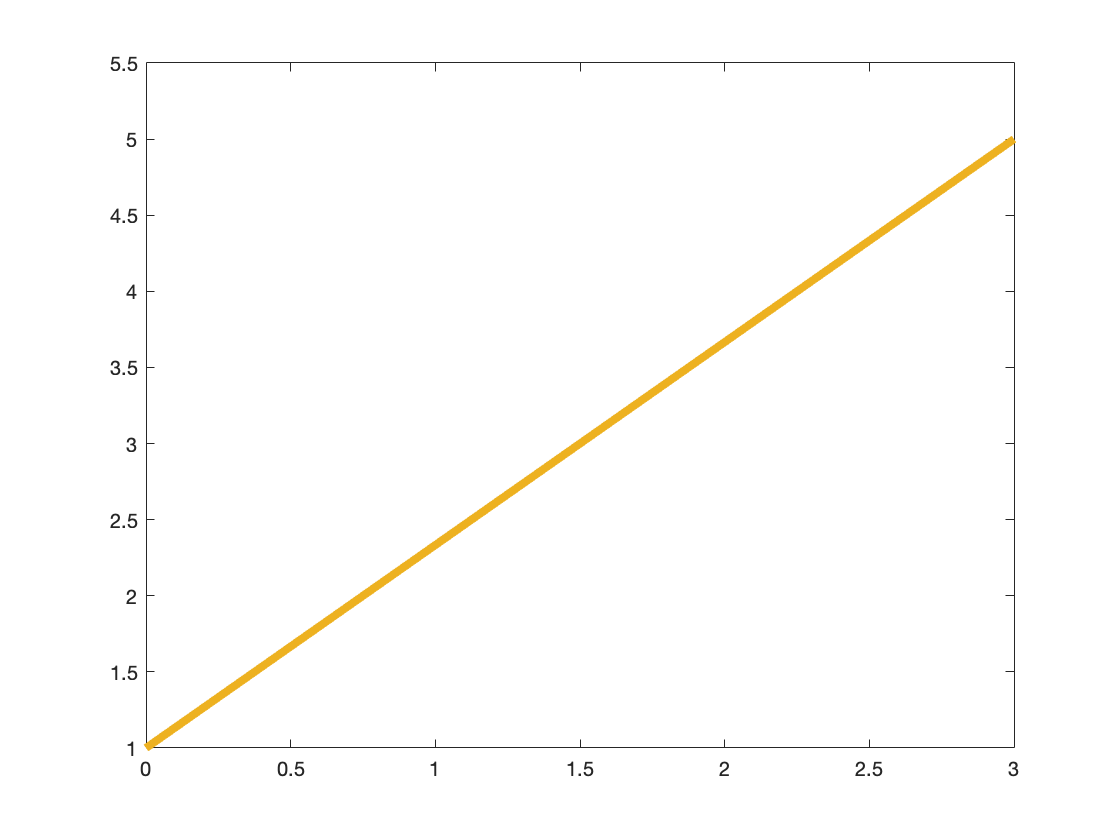

for i = 1:100
    if x_mid(end) == xT
        break
    else if sign(x_mid(end) - xT) == sign(x_a(end)-xT)
        v1 = v_mid;
        [T, Y] = ode45(@(t, x) myODE(t,x), [0 3], [x0 v1]);
        t_a = T; % for plotting
        x_a = Y(:, 1);
    else
        v2 = v_mid;
        [T, Y] = ode45(@(t, x) myODE(t,x), [0 3], [x0 v2]);
        t_b = T; % for plotting
        x_b = Y(:, 1);
    end
    end
    v_mid = (v1 + v2)/2;

[T, Y] = ode45(@(t, x) myODE(t,x), [0 3], [x0 v_mid]);
t_mid = T; % for plotting
x_mid = Y(:, 1);
plot(t_a, x_a, t_mid, x_mid, '--', t_b, x_b, 'linewidth', 4)
pause(0.1)
end

This very quickly converges to the true solution.  To see how the algorithm is working it may be useful to test it out with v1 and v2 that gives us a much larger gap.

### Finite Differences

#### I borrowed the old notes for this, but changed a few things up in the video.

We will now start to develop a method for solving boundary value problems numerically.  In particular, we will start by solving the problem 

$\ddot{x} = 0$, with $x(0) = x_0$ and $x(T) = x_T$.  

We already know that the solution is 

$x(t) = \frac{x_T - x_0}{T}t + x_0$, 

and we would love to find a numerical method that would give us this formula for $x(t)$.  Unfortunately, this is generally a hopeless task.  (For more complciated equations, it is usually not even possible on paper, and it is certainly not something we can expect MATLAB to do.)  Instead, we will try to approximate $x(t)$ at many different times.  In particular, we will use the same setup that we had for initial value problems and choose a set of evenly spaced $t$ values: $t_0$, $t_1$, $t_2$, ..., $t_{N-1}$, $t_N$.  In general, it only really makes sense to solve a boundary value problem between the two times used for boundary conditions, so we will choose $t_0 = 0$ and $t_N = T$.  Since these times are evenly spaced, we can write each time as $t_k = k\Delta t$, where $\Delta t = T/N$.  

Our goal is to find the values of $x$ at each of these $t$-values.  That is, we would like to find $x(t_0)$, $x(t_1)$, $x(t_2)$, ..., $x(t_{N-1})$, $x(t_N)$.  Of course, we can't hope to find those values exactly with a numerical method, so we will only obtain approximations $x_0$, $x_1$, $x_2$, ..., $x_{N-1}$, $x_N$.  We therefore need to find an equation (or several equations) for these $x_k$'s.  Actually, we already know two of these points.  $x_0$ is just our first boundary condition and $x_N = x_T$ is just our second boundary condition.  We therefore only have to solve for $x_1$ through $x_{N-1}$.  We call these $x$-values the *interior values* (as opposed to the boundary values) and the corresponding times $t_1$ through $t_{N-1}$ are called the *interior points* (or interior times).  Notice that there are $N+1$ total points, but only $N-1$ interior points.  

The key to our approach is to approximate the second derivative $\ddot{x}$ in our differential equation with a finite difference scheme.  In particular, we already saw in last week's activity that we could approximate the second derivative of a function $f$ with the second order central difference scheme


$$f''(t) \approx \frac{f(t - \Delta t) - 2f(t) + f(t + \Delta t)}{\Delta t^2}.$$


Translating this into our new notation, we have 


$$\ddot{x}(t) \approx \frac{x(t - \Delta t) - 2x(t) + x(t + \Delta t)}{\Delta t^2}.$$


This is true for any time $t$.  In particular, we could use the first interior time $t_1$, which gives us the equation 


$$\ddot{x}(t_1) \approx \frac{x(t_1 - \Delta t) - 2x(t_1) + x(t_1 + \Delta t)}{\Delta t^2} = \frac{x(t_0) - 2x(t_1) + x(t_2)}{\Delta t^2}.$$


We don't know what $x(t_1)$ or $x(t_2)$ are, but we do know that this expression is supposed to be approximately equal to zero (because $\ddot{x}(t) = 0$ for any time).  We can just use this as the definition of our approximations: 


$$\frac{x_0 - 2x_1 + x_2}{\Delta t^2} = 0.$$


Similarly, if we plug in $t = t_2$, we get the equation 


$$\ddot{x}(t_2) \approx \frac{x(t_2 - \Delta t) - 2x(t_2) + x(t_2 + \Delta t)}{\Delta t^2} = \frac{x(t_1) - 2x(t_2) + x(t_3)}{\Delta t^2}.$$


Again, we know that this is supposed to be approximately equal to zero, so we can take this as a definition for our approximations: 


$$\frac{x_1 - 2x_2 + x_3}{\Delta t^2} = 0.$$


We can repeat this process for any interior time $t_k$ and we get the formula 


$$\frac{x_{k-1} - 2x_k + x_{k+1}}{\Delta t^2} = 0.$$


We therefore have the following system of equations: 

$(1/\Delta t^2)(x_0 - 2x_1 + x_2) = 0$, 

$(1/\Delta t^2)(x_1 - 2x_2 + x_3) = 0$, 

...

$(1/\Delta t^2)(x_{N-3} - 2x_{N-2} + x_{N-1}) = 0$, 

$(1/\Delta t^2)(x_{N-2} - 2x_{N-1} + x_{N}) = 0$.  

Notice that there are only $N-1$ equations here, because we only plugged in interior times, not the boundary times.  (If we used boundary times $t_0$ or $t_N$ in these equations, then we would need $x$-values from outside of our interval $[0, T]$.)  

Also note that $x_0$ and $x_N$ are actually already known - they are our boundary values - and so we should really move them over to the right side of our equations.  We are then left with 


$$(1/\Delta t^2)(- 2x_1 + x_2) = -x_0/\Delta t^2,$$


$(1/\Delta t^2)(x_1 - 2x_2 + x_3) = 0$, 

...

$(1/\Delta t^2)(x_{N-3} - 2x_{N-2} + x_{N-1}) = 0$, 


$$(1/\Delta t^2)(x_{N-2} - 2x_{N-1}) = -x_T/\Delta t^2.$$


This is a linear system of equations for the interior values $x_1$, ..., $x_{N-1}$, and so we can rewrite it as a matrix equation $A\mathbf{x} = \mathbf{b}$.  We get 


$$\frac{1}{\Delta t^2}\left(\begin{array}{c} -2 & 1 & 0 & \cdots & 0 \\ 1 & -2 & 1 & \cdots & 0 \\ \vdots & \ddots & \ddots & \ddots & \vdots \\ 0 & \cdots & 1 & -2 & 1 \\ 0 & \cdots & 0 & 1 & -2 \end{array} \right)\left(\begin{array}{c} x_1 \\ x_2 \\ \vdots \\ x_{N-2} \\ x_{N-1} \end{array} \right) = \left( \begin{array}{c} -x_0/\Delta t^2 \\ 0 \\ \vdots \\ 0 \\ -x_T/\Delta t^2 \end{array} \right).$$


We know several methods to solve a system like this  We could use Gaussian elimination, $LU$ decomposition, or even an iterative method like Jacobi or Gauss-Seidel.  We will just use the backslash operator, but this is another example of why linear systems are so important in numerics.  

Notice that this method is not a time-stepper, unlike the methods we developed for initial value problems.  That is, we can't solve for $x_1$ and then $x_2$ and then $x_3$, etc.  Instead, we have to solve the whole system at once.  

As an example, let's implement this in MATLAB to solve 

$\ddot{x} = 0$ with $x(0) = 1$ and $x(3) = 5$.  

We will choose $\Delta t = 0.1$.  

x0 = 1;
xT = 5;
T = 3;
dt = 0.1;

t = 0:dt:T;
n = length(t);

Notice that $n$ is the total number of points, including the boundary points.  There are only $n-2$ interior points, so we need to make an $(n-2)\times (n-2)$ system of equations.  We can make a matrix of the right form with the code 

v = -2*ones(n-2, 1);
u = ones(n-3, 1);
A = (1/dt^2)*(diag(v) + diag(u, 1) + diag(u, -1));

You already constructed this matrix in a homework problem, so I won't spend any extra time explaining the code above.  

We also have to make the vector $\mathbf{b}$ for the right hand side.  This vector is mostly zeros, but the first and last entry depend on the boundary conditions.  We can implement this in MATLAB with 

b = zeros(n-2, 1);
b(1) = -x0/dt^2;
b(end) = -xT/dt^2;

Finally, we can solve for all of the interior $x$-values with the command 

x_int = A\b;

Keep in mind that this vector does not include the boundary values.  Usually we want to know all of the $x$-values, not just the interior values, but this is easy to fix.  The first and last $x$-value are just the two boudnary conditions, so we can write 

x = [x0; x_int; xT];

We would like to plot our solution and compare it to the formula we found by hand.  There is a small technical difficulty here.  The problem is that the code `t = 0:dt:T` produces a row vector, but the backslash command produces a column vector.  It is unwise to compare vectors of different shapes, so we should make both `t` and `x` row vectors or make both `t` and `x` column vectors.  For no particular reason, let's make `t` a column vector: 

t = t';

Now we can plot our approximation alongside the true solution.  

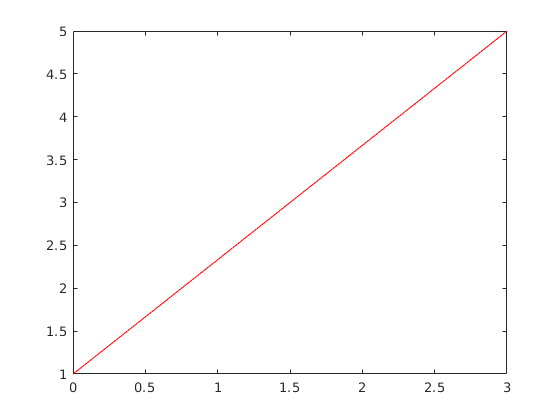

x_true = @(t)((xT - x0)/T * t + x0);
plot(t, x_true(t), 'k', t, x, 'r')

We can't even see both graphs, which is a good sign that we found a good approximation.  To confirm, we could check the maximum error

err = max(abs(x - x_true(t)))

err = 1.4655e-14

This is quite small, so we did indeed find a good approximation.  In general, we can't expect the error to be quite this small, but it turns out that this differential equation was so simple that our difference scheme was actually exact.  Because of that, the only error actually arose from the backslash command and not our BVP solver.  

### Problems With No Solution

Remember that not all boundary value problems have a solution.  In particular, consider

$\ddot{x} + x = 0$ with $x(0) = x_0$ and $x(\pi) = 5$

does not have a solution.  What happens when we try to solve this problem using our numerical method?  

x0 = 0;
xT = 5;
T = pi;

dt = 0.1;
t = (0:dt:T)';
n = length(t);

v = -2*ones(n-2, 1);
u = ones(n-3, 1);
A = (1/dt^2)*(diag(v) + diag(u, 1) + diag(u, -1));

I = eye(n-2);

b = zeros(n-2, 1);
b(1) = -x0/dt^2;
b(end) = -xT/dt^2;

x_int = (A + I)\b;
x = [x0; x_int; xT];

It no longer makes sense to calculate the error, but we can still plot our approximate solution.  

plot(t, x, 'r')

We got an answer that looks roughly the same as last time, but remember that there isn't supposed to be a solution.  What is going on here?  To see the problem, let's try using a smaller $\Delta t$.  If there was a unique solution, we would expect to get closer to it as we made $\Delta t$ smaller.  

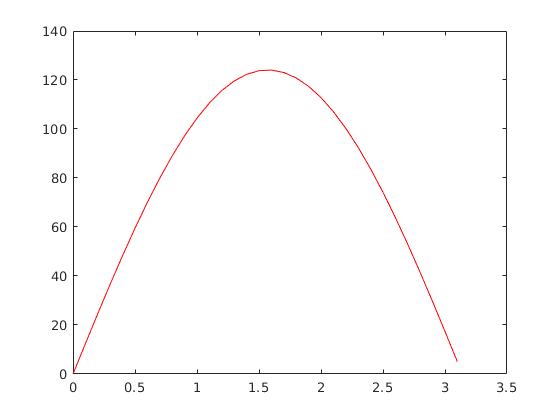

dt = 0.01;
t = (0:dt:T)';
n = length(t);

v = -2*ones(n-2, 1);
u = ones(n-3, 1);
A = (1/dt^2)*(diag(v) + diag(u, 1) + diag(u, -1));


I = eye(n-2);

b = zeros(n-2, 1);
b(1) = -x0/dt^2;
b(end) = -xT/dt^2;

x_int = (A + I)\b;
x = [x0; x_int; xT];

plot(t, x, 'r')

Notice the scale on the $y$-axis.  Our approximations are not getting closer to anything.  Instead, they are growing infinitely large as we shrink $\Delta t$.  This is typical behavior when the BVP doesn't have a solution.  The numerical method will always give you an answer, but those answers won't converge as you shrink $\Delta t$.  

### Problems With Many Solutions

Similarly,

$\ddot{x} + x = 0$ with $x(0) = 0$ and $x(\pi) = 0$ has infinitely many solutions.  If we try to solve this with our numerical method, we get 

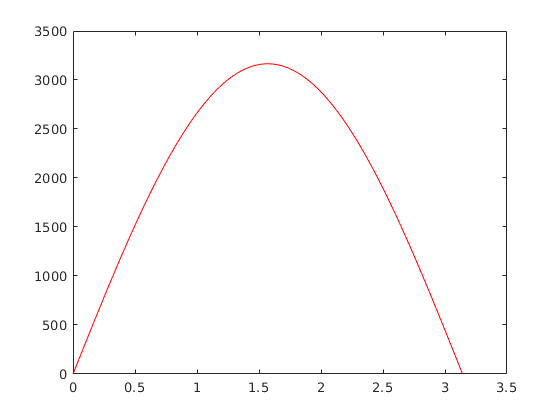

x0 = 0;
xT = 0;
T = pi;

dt = 0.1;
t = (0:dt:T)';
n = length(t);


v = -2*ones(n-2, 1);
u = ones(n-3, 1);
A = (1/dt^2)*(diag(v) + diag(u, 1) + diag(u, -1));

I = eye(n-2);

b = zeros(n-2, 1);
b(1) = -x0/dt^2;
b(end) = -xT/dt^2;

x_int = (A + I)\b;
x = [x0; x_int; xT];

plot(t, x, 'r')

In this case, we get $x(t) = 0$, which really is a solution to our differential equation.  It turns out that we will still get the same answer no matter how we change $\Delta t$.  This behavior is a little less common.  In general, if your BVP has many solutions, then the numerical solutions might converge to one of those solutions or they might not converge at all.  

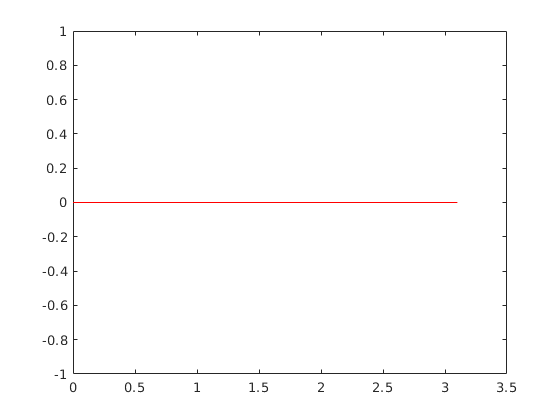

function dx = myODE(t,x)
    dx1 = x(2);
    dx2 = 0;
    dx = [dx1; dx2];
end